**Date: 2026-01-30  **

**Author: Dr. Gianluca Santesarti**

**Affiliation: Sapienza University of Rome, Dept. of Mechanical and Aerospace Engineering**

**--**

**SINGLE DIRECTION FUNCTIONAL GRADING - LINEAR STIFFNESS GRADING - SKELETAL-BASED STRUCTURE**

**FOR MEDCON 2026 CONFERENCE PAPER SUBMISSION**

**REFERENCE:**

**Gyroid - Skeletal -  Material Ti-&Al-V - Cell size 2.5 mm**

**test to determine the a and b coefficients of the isovalue-relative density relation  **

**\rho_r = a*c + b**

**1st Structure - v1 = +c -- c = 0.735**

clc;
clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.74; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 0.7400
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

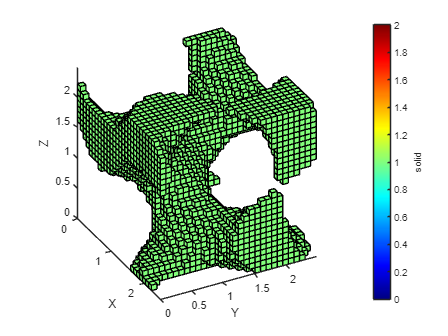

axesVoxel = myCell.plot("voxel","solid");

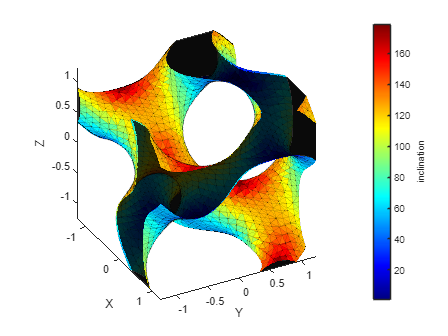

axesVoxel = myCell.plot("SurfMesh","inclination");

% X = ['for c = 0.1, relative volume = ' num2str(myCell.M.relativeVolume*100) '%']
% disp(X)
isoval_rheldens_array = [V1; myCell.M.relativeVolume*100];

**2nd Structure - v1 = +c -- c = 0.30**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.30; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 0.3000
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

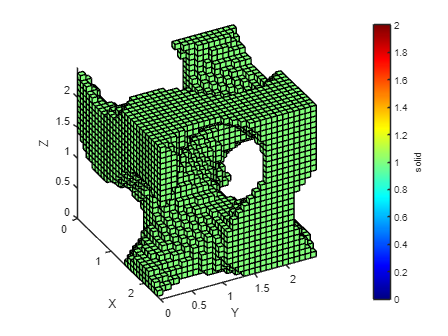

axesVoxel = myCell.plot("voxel","solid");

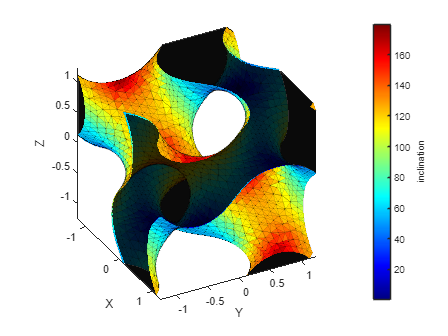

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =     0.3000
   39.9599


isoval_rheldens_array = [isoval_rheldens_array newdata];

**3rd Structure - v1 = +c -- c = -0.152**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = -0.152; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: -0.1520
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

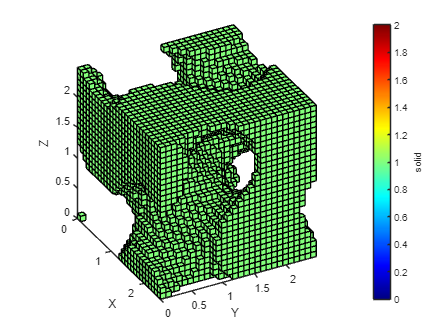

axesVoxel = myCell.plot("voxel","solid");

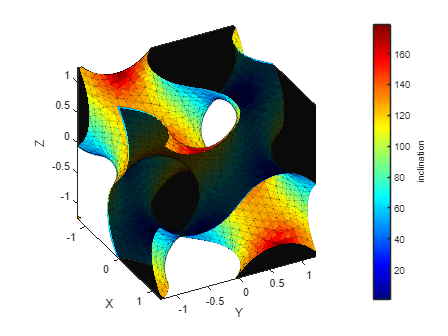

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =    -0.1520
   54.7103


isoval_rheldens_array = [isoval_rheldens_array newdata];

**4th Structure - v1 = +c -- c = -0.63**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = -0.63; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: -0.6300
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

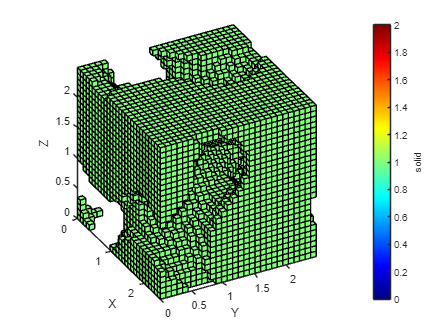

axesVoxel = myCell.plot("voxel","solid");

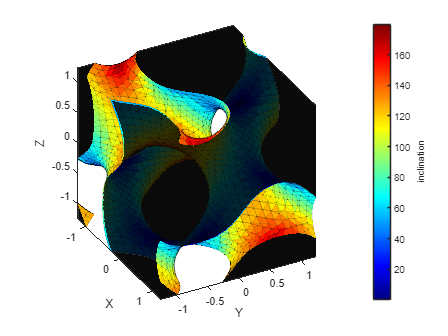

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =    -0.6300
   70.1576


isoval_rheldens_array = [isoval_rheldens_array newdata];

**5th Structure - v1 = +c -- c = -1.1**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = -1.05; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: -1.0500
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

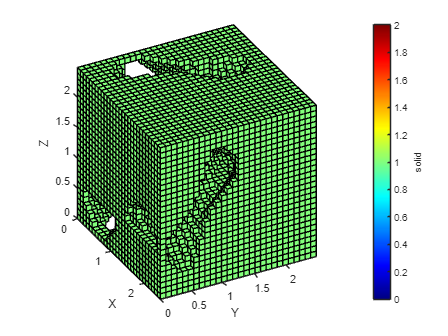

axesVoxel = myCell.plot("voxel","solid");

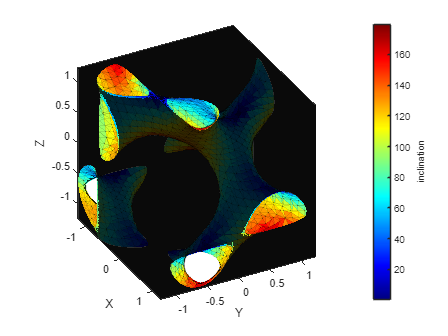

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =    -1.0500
   84.8351


isoval_rheldens_array = [isoval_rheldens_array newdata];

**RESULTS OF 2026-03-30 **

** isoval_rheldens_array = **

**0.740000000000000	0.300000000000000	-0.152000000000000	-0.630000000000000	-1.05000000000000**

**26.0021865889213    	39.9599125364432	        54.7102769679300	        70.1576166180758	        84.8350947521866**

**the linear relationship between the isovalue c and the relative density \rho_r is confirmed**

**Array Structure  Ncells [3,1,1] with Porosity 74%  -  v1 = +c -- c = 0.74**

% clc;
% clear all;

N_xcells = 3; % number of cells along x-direction 

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.74; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 0.7400
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

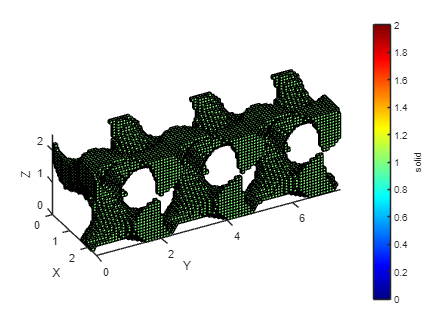

axesVoxel = myCell.plot("voxel","solid");

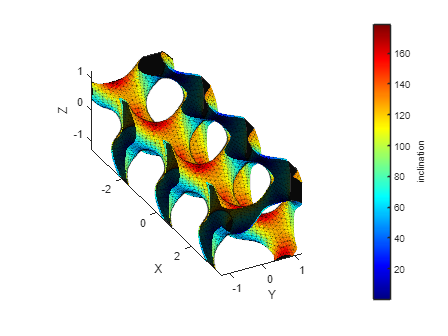

axesVoxel = myCell.plot("SurfMesh","inclination");

**Array Structure  Ncells [3,1,1] with Porosity 15.2%  -  v1 = +c -- c = -1.05**

% clc;
% clear all;

N_xcells = 3; % number of cells along x-direction 

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = -1.05; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: -1.0500
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

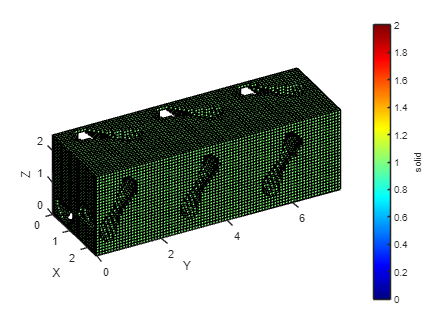

axesVoxel = myCell.plot("voxel","solid");

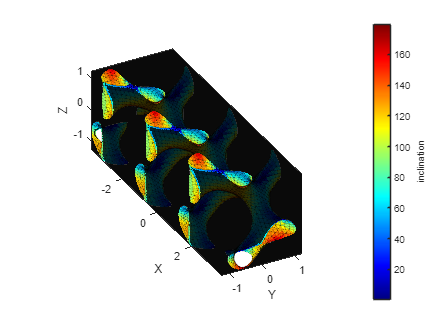

axesVoxel = myCell.plot("SurfMesh","inclination");

**-----------------**

**-----START --- 2026-04-10 - LOW RESOLUTION 4 INVENTOR**

**Array Structure  Ncells [3,1,1] with Porosity 74%  -  v1 = +c -- c = 0.74 - LOW RESOLUTION**

% clc;
% clear all;

N_xcells = 3; % number of cells along x-direction 

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.74; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.125; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 0.7400
           v2: 0
    voxelSize: 0.1250
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

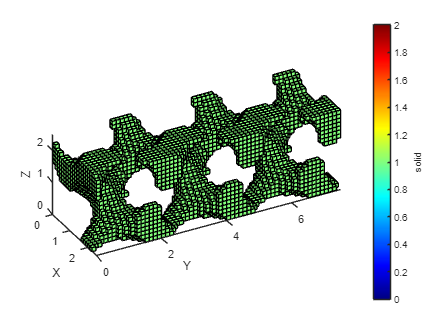

axesVoxel = myCell.plot("voxel","solid");

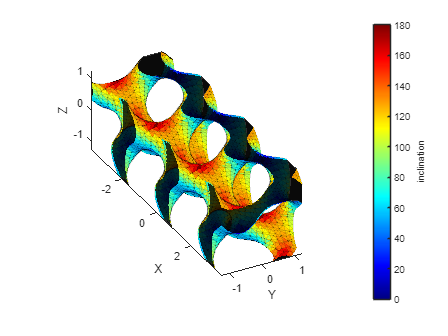

axesVoxel = myCell.plot("SurfMesh","inclination");

**Array Structure  Ncells [3,1,1] with Porosity 15.2%  -  v1 = +c -- c = -1.05  - LOW RESOLUTION**

% clc;
% clear all;

N_xcells = 3; % number of cells along x-direction 

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = -1.05; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.125; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: -1.0500
           v2: 0
    voxelSize: 0.1250
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

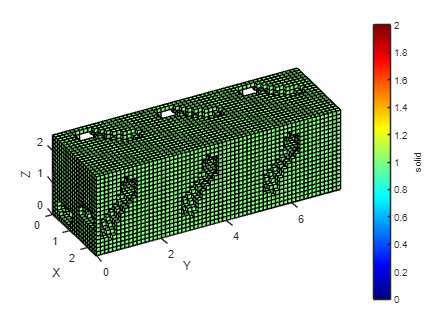

axesVoxel = myCell.plot("voxel","solid");

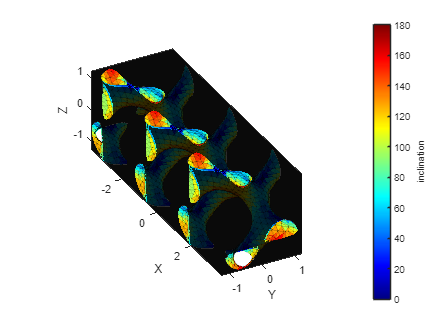

axesVoxel = myCell.plot("SurfMesh","inclination");

**Array Structure  Ncells [3,1,1] with Porosity 15.2%  -  v1 = +c -- c = -1.05  - MEDIUM RESOLUTION**

% clc;
% clear all;

N_xcells = 3; % number of cells along x-direction 

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = -1.05; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
% VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
% CELLSIZE = 8; % Unit cell size in mm
VOXSIZE = 0.10; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: -1.0500
           v2: 0
    voxelSize: 0.1000
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

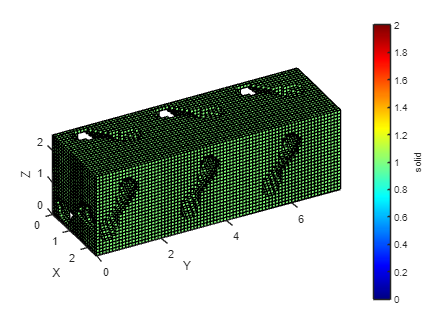

axesVoxel = myCell.plot("voxel","solid");

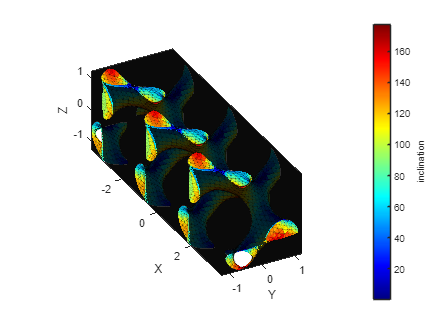

axesVoxel = myCell.plot("SurfMesh","inclination");

**-----END --- 2026-04-10 - LOW RESOLUTION 4 INVENTOR**

**2026-03-31 **

**SINGLE DIRECTION FUNCTIONAL GRADING - LINEAR STIFFNESS GRADING - SKELETAL-BASED STRUCTURE**

**LINEAR FIT to determine the a and b coefficients of the isovalue-relative density relation  **

**\rho_r = a*c + b**

**RESULTS **

**a = -32.78    b= 49.94,**

** \rho_r [%] = -32.78*c + 49.94**

**0.740000000000000	0.300000000000000	-0.152000000000000	-0.630000000000000	-1.05000000000000**

**26.0021865889213    	39.9599125364432	        54.7102769679300	        70.1576166180758	        84.8350947521866**

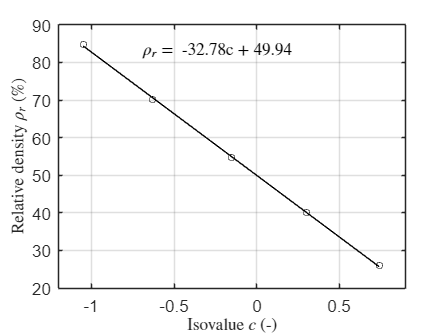

isovalues = [-1.05, -0.63, -0.152, 0.3, 0.74];
rhel_dens = [84.84, 70.16, 54.71, 39.96, 26.00]; % [%]
linear_fit = polyfit(isovalues,rhel_dens,1);
rhel_dens_fit = linear_fit(1)*isovalues + linear_fit(2);

figure
plot(isovalues,rhel_dens,'o k','LineWidth',0.5) 
hold on;
plot(isovalues,rhel_dens_fit,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 
xlabel('Isovalue $c$ (-)','interpreter','latex','fontsize',16);
ylabel('Relative density $\rho_r$ (\%)','interpreter','latex','fontsize',16);
xlim([-1.2 0.9])
ylim([20 90])

% lgd = legend([P1 P2 P3 P4 H2O],{'$\bar{\eta}$','$\bar{\eta}_W$','$\bar{\eta}_T$','$\bar{\eta}_L$','bulk water'},'interpreter','latex','Location','northeast');
% lgd.FontSize = 12;

hold off
grid on
box on
string = append('$\rho_r =$ ', sprintf("%.2f", linear_fit(1)), 'c + ', sprintf("%.2f", linear_fit(2)));
text(-0.7,83,string,'fontsize',16,'interpreter','latex')

**2026-04-09**

**GIBSON-ASHBY MODEL FITTING**

rhel_dens_fitting = [26.00, 39.96, 54.71, 70.16, 84.84]/100; % [-]

mat_stiff_fitting = [13.39, 66.85, 84.08, 129.79, 189.5874]; % [GPa]

fit_mat_stiff = fit(rhel_dens_fitting',mat_stiff_fitting','power1');
fit_mat_stiff_N = 1.718;
fit_mat_stiff_K = 247.9; % (GPa)

RangeRD_fit = linspace(rhel_dens_fitting(1),rhel_dens_fitting(end));
MatStiff_fit = (RangeRD_fit.^fit_mat_stiff_N)*fit_mat_stiff_K; % (GPa)

figure
P1 = plot(rhel_dens_fitting*100,mat_stiff_fitting,'o k','LineWidth',0.5) % [%] [GPa]

P1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [26 39.9600 54.7100 70.1600 84.8400]
              YData: [13.3900 66.8500 84.0800 129.7900 189.5874]

  Show all properties


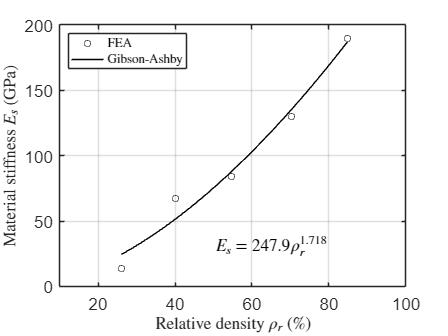

hold on;
P2 = plot(RangeRD_fit*100,MatStiff_fit,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 
xlabel('Relative density $\rho_r$ (\%)','interpreter','latex','fontsize',16);
ylabel('Material stiffness $E_{s}$ (GPa)','interpreter','latex','fontsize',16);
xlim([10 100])
ylim([0 200])

lgd = legend([P1 P2],{'FEA','Gibson-Ashby'},'interpreter','latex','Location','northwest');
lgd.FontSize = 12;

hold off
grid on
box on
string = append('$E_s = 247.9\rho_r^{1.718}$');
text(50,30,string,'fontsize',16,'interpreter','latex')

**STIFFNESS LINEAR GRADING OPTIMIZATION - TARGET DESIGN - 3x1x1 unit cells**

UnitCellSize = 2.5; %(mm)
N_xcells = 3; % number of cells along x-direction 

x_A = -(UnitCellSize)/2*N_xcells; % (mm)
x_B = (UnitCellSize)/2*N_xcells; % (mm)
y_A = 24.5; % (GPa)
y_B = 186.9; % (GPa)

alpha = (y_B - y_A)/(x_B - x_A); % result 21.6533
beta = (y_A*x_B - y_B*x_A)/(x_B - x_A); % result 105.7

**STIFFNESS LINEAR GRADING OPTIMIZATION - OPTIMAL ISOVALUE c(x)**

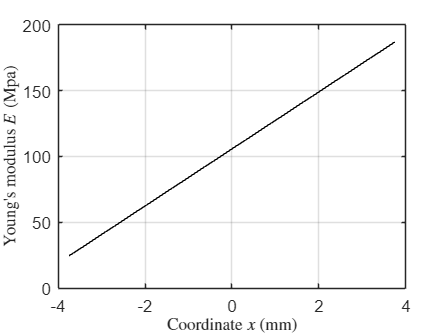

isovalue_opt_a1 = 1/(linear_fit(1)/100); % result -3.0502
isovalue_opt_a2 = -(linear_fit(2)/100)/(linear_fit(1)/100); % result 1.5233

%test
isovalue_opt_funct = @(x) -3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233; %test

x_array_test = [x_A:0.1:x_B];
isovalue_opt_array_test = isovalue_opt_funct(x_array_test);
reldens_opt_array_test = linear_fit(1)/100*isovalue_opt_array_test + linear_fit(2)/100;
YoungMod_opt_array_test = fit_mat_stiff_K*reldens_opt_array_test.^fit_mat_stiff_N;

%%%%%%%%%%%%%%%% CHECK START
figure
plot(x_array_test(:), YoungMod_opt_array_test,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 

xlabel('Coordinate $x$ (mm)','interpreter','latex','fontsize',16);
ylabel('Young''s modulus $E$ (Mpa)','interpreter','latex','fontsize',16);
xlim([-4 4])
% ylim([0 7])

grid on
box on

%%%%%%%%%%%%%%%% CHECK END

isovalue_opt = '-3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233';

**STIFFNESS LINEAR GRADING OPTIMIZATION - SINGLE DIRECTION**

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID
myEQUATION = [func2str(EQ0) isovalue_opt];

TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.0; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.089; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233
           v1: 0
           v2: 0
    voxelSize: 0.0890
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]


calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

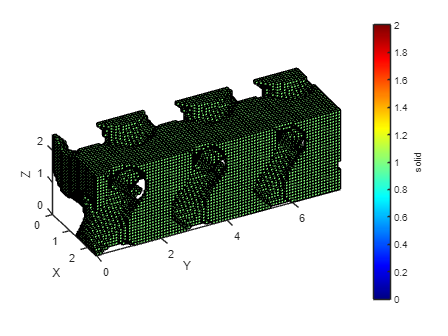

axesVoxel = myCell.plot("voxel","solid");

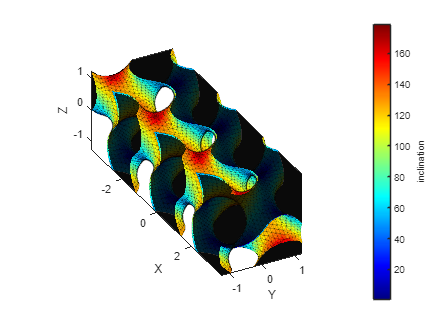

axesVoxel = myCell.plot("SurfMesh","inclination");

**-----------------**

**-----START --- 2026-04-10 - LOW RESOLUTION 4 INVENTOR**

**STIFFNESS LINEAR GRADING OPTIMIZATION - SINGLE DIRECTION**

isovalue_opt = '-3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233';

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID
myEQUATION = [func2str(EQ0) isovalue_opt];

TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.0; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.125; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 2.5; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-3.0502*((21.6533*x+105.7)/247.9).^(1/1.718)+1.5233
           v1: 0
           v2: 0
    voxelSize: 0.1250
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]


calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

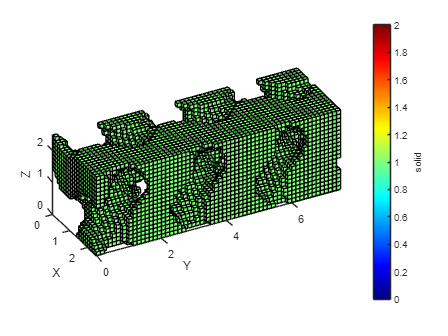

axesVoxel = myCell.plot("voxel","solid");

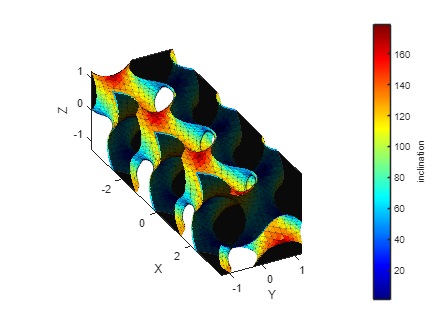

axesVoxel = myCell.plot("SurfMesh","inclination");

**STOP 2026-04-10**